% MSE = immse(grayI2_200,grayI2)
% peakval = 255
% PSNR=10*log10(peakval^2/MSE)
clear;
clc;
B = 0;
A = [1 2 3; 4 5 6; 7 8 9]

A =      1     2     3
     4     5     6
     7     8     9


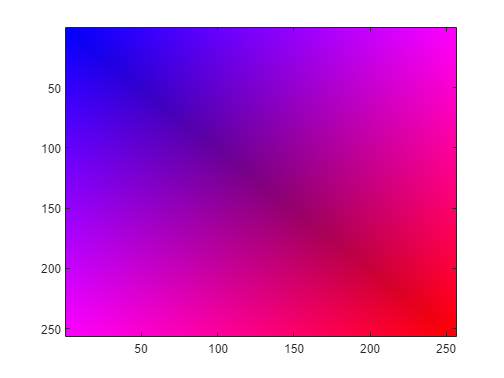


% 
% grayI2 = im2double(grayI2);
% grayI2_200 = im2double(grayI2_200);
% 
% grayI2 = grayI2*255;
% grayI2_200 = grayI2_200*255;
% 
% suma = 0;
% 
% for i = 1:256
%     for j = 1:384
%         grayI2(i,j);
%         grayI2_200(i,j);
%         suma = suma + (grayI2(i,j)-grayI2_200(i,j))^2;
%     end
% end
% suma
% mse = (suma/98304)
% PSNR2=10*log10(peakval^2/mse)


% R0 = [0 0;
%       0 255]
% G0 = [0 0;
%       0 0]
% B0 = [255 0;
%       0 0]
% 
% 
% RGB0(:,:,1) = R0;
% RGB0(:,:,2) = G0;
% RGB0(:,:,3) = B0;
% 
% imagesc(RGB0)



% for i = 1:N/2
%     for j = 1:i
%         B(i,i)=255/N;
%         B(i,j)=255/N;
%         B(j,i)=255/N;
%         R(i,i)=(0+i)/N;
%         R(i,j)=(0+i)/N;
%         R(j,i)=(0+i)/N;
%         R(N-i+1,N-i+1)=255/N;
%         R(N-i+1,N-j+1)=255/N;
%         R(N-j+1,N-i+1)=255/N;
%         B(N-i+1,N-i+1)=(0+i)/N;
%         B(N-i+1,N-j+1)=(0+i)/N;
%         B(N-j+1,N-i+1)=(0+i)/N;
%     end
% end
% 
% for i = N/2:3*N/4
%     for j = 1:i
%         B(N+1-i,N+1-i)=255/N;
%         B(N+1-i,N+1-j)=255/N;
%         B(N+1-j,N+1-i)=255/N;
%     end
% end
% 
% RGB1(:,:,1) = R;
% RGB1(:,:,2) = G*0;
% RGB1(:,:,3) = B;
% imagesc(RGB1)

% haciendo triangulos
% for i = 1:N
%     for j = 1:N-i
%         %B(i,j) = (255)/N;
%         R(i,j)= (i/N);
% 
%         %R(N-i,N-j) = 255/N;
%     end
% end
% 
% RGB1(:,:,1) = R;
% RGB1(:,:,2) = G*0;
% RGB1(:,:,3) = B;
% imagesc(RGB1)

% R2 = [0 0 0 0; 
%      0 0 0 0;
%      0 0 255 255;
%      0 0 255 255];
% G2 = [0 0 0 0; 
%      0 0 0 0;
%      0 0 0 0;
%      0 0 0 0];
% B2 = [0 0 0 0; 
%      0 0 0 0;
%      0 0 0 0;
%      0 0 0 0];
% 
% for i5 = 1:4
%     B2(1,i5) = 1;
%     B2(i5,1) = 1;
% end
% 
% RGB2(:,:,1) = R2;
% RGB2(:,:,2) = G2;
% RGB2(:,:,3) = B2;
% imagesc(RGB2)
N=256;
R = zeros(N);
G = zeros(N);
B = zeros(N);


for i = 1:N
        for j = 1:i
            R(i,i)=(0+i)/N;
            R(i,j)=(0+i)/N;
            R(j,i)=(0+i)/N;
            B(N-i+1,N-i+1)=(0+i)/N;
            B(N-i+1,N-j+1)=(0+i)/N;
            B(N-j+1,N-i+1)=(0+i)/N;
        end
end

RGB1(:,:,1) = R;
RGB1(:,:,2) = G*0;
RGB1(:,:,3) = B;
imagesc(RGB1)